    load nasnet_mobile.mat
signds = imageDatastore("D:\college\FYP\Experimenting\test\stopping","IncludeSubfolders",true,"LabelSource","foldernames");
signNames = signds.Labels;
[signTrain,signTest] = splitEachLabel(signds,0.8,"randomized");

% Augmentation
resizeTrainImgs = augmentedImageDatastore([224 224],signTrain);
resizeTestImgs = augmentedImageDatastore([224 224],signTest);

numClasses = numel(categories(signds.Labels));

% Setting Options
opts = trainingOptions("sgdm","InitialLearnRate",0.001,"MaxEpochs",5,"VerboseFrequency",2);

% Training the network
[Network,info] = trainNetwork(resizeTrainImgs,nasnet_mobile,opts);

Training on single CPU.
Initializing input data normalization.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:36 |       50.00% |       1.0217 |          0.0010 |
|       2 |           2 |       00:01:14 |       51.16% |       0.7728 |          0.0010 |
|       4 |           4 |       00:03:03 |       56.98% |       0.6598 |          0.0010 |
|       5 |           5 |       00:03:58 |       59.30% |       0.5885 |          0.0010 |
|========================================================================================|
Training finished: Max epochs completed.


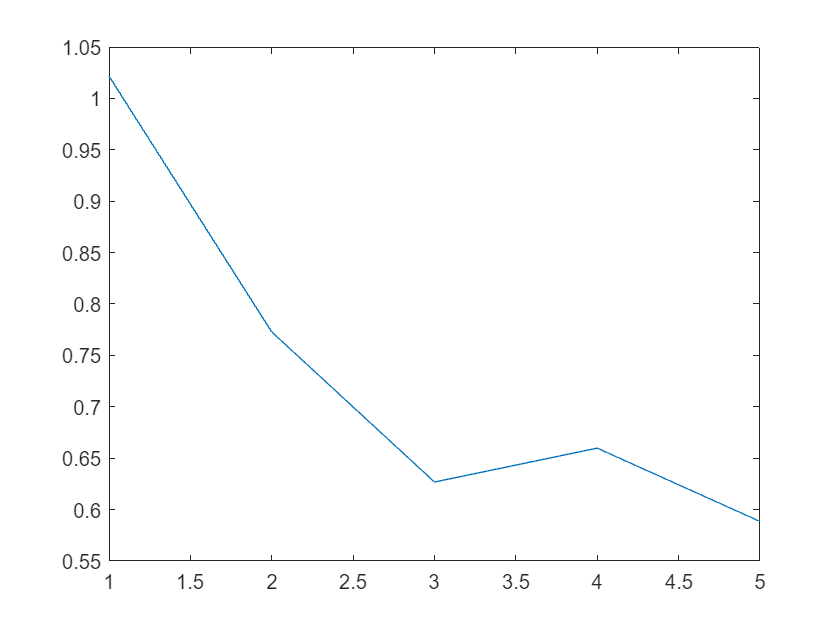


% Evaluating Performance
plot(info.TrainingLoss);

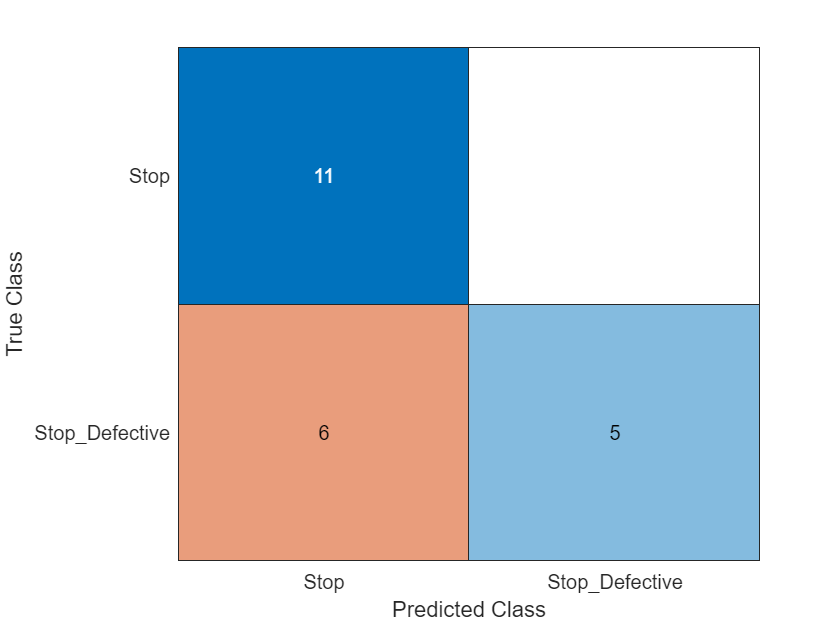



% Prediction
signPrediction = classify(Network,resizeTestImgs);

signActual = signTest.Labels;

% Comparison
numCorrect = nnz(signPrediction == signActual);
fracCorrect = numCorrect/numel(signPrediction);

% Confusion Chart
confusionchart(signActual,signPrediction);